clear ;
clc;
close all;
MAX_EPISODES=1;
tic;
% fid = fopen('test.txt','w');
% h = waitbar(0,'the net is training...');
step_count = 0;
set_param('fangzhendp','SimulationCommand','Stop');
load_system('fangzhendp');
load("P_US06.mat");
load("engineMap1.mat");% 转速，功率，油耗
load('engPowermax.mat');%发动机最大功率map图 转速 功率w
load('motPowermax.mat');%电机最大功率map图

load net_96ac_11in.mat%87训练精度
load P_duofenlei.mat

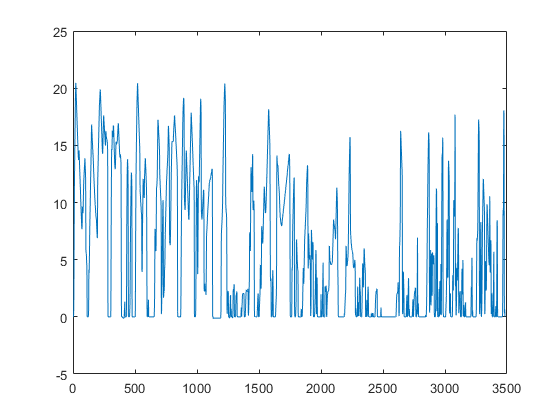

load v_density2.mat
% 拼接不同车流密度的车速曲线 10：452.8 40：532.4 70：807.8 100：1694.5
v_density = [v(1).v(1:452,1);v(2).v(1:532);v(3).v(1:807);v(4).v(1:1694)];

plot(v_density)



% vt+1等于 P 一行中最大概率对应的车速
%前轮盘式制动器
Abf = 0.0017;%制动气缸表面积 m^2
cbf =  1.0;%具体的制动因素
eta_bf =0.99; %效率
rbf = 0.11;%有效摩擦半径 m
mu_bf= 0.22;%摩擦系数0.3

%后轮鼓式制动器
Abb = 4e-4; %制动气缸表面积 m^2 0.0004
cbb =  2.7;%具体的制动因素
eta_bb =0.98; %效率
rbb = 0.095;%有效摩擦半径 m
mu_bb= 0.22;%摩擦系数0.3
brake_factor = 2*(2*Abf*eta_bf*mu_bf*rbf*cbf+2*Abb*eta_bb*mu_bb*rbb*cbb);

for ii = 1:MAX_EPISODES %驾驶循环跑的次数，训练循环的次数，迭代的次数,每次循环时进行各个参数的初始化
    %     waitbar(ii/MAX_EPISODES);
    % 仿真参数
    load_eng=0.5;
    load_motor =0.5;
    Brake_Pressure_EMS=0;
    Start_Switch_eng=1;
    clutch_release_motor = 1;%电机与变速器之间的离合器分离，此离合器是根据发动机的load而决定是否开启，因为此混动是个轻混，电机无法独立提供动力
    clutch_release_eng =0;%发动机与电机之间的离合器分离
    FixedStep = 0.1;
    l=1220;%驾驶循环时间
    %     StopTime =1220;
    StopTime =l;
    t=StopTime/FixedStep+1;
    
    % 预测参数
    step = 10; %预测步长
    %     v_p_memory =zeros(t,step+1);
    %     a_p_memory = zeros(t,step+1);
    v_p = zeros(t,step+1);%下一时刻车速
    a_p = zeros(t,step+1);%下一时刻加速度
    T_req = zeros(t,step+1);
    P_duobu = zeros(size(P,1),size(P,2),step);
    delta_t = 1; %每一预测步长的时间
    ds = 0.1;%每个状态的分配步长
    %     amax=max(v_a(:,2));%最大加速度
    
    
    %发动机参数约束
    idle_speed = 720;
    fc_idle = 9.6e-5;
    c=0;%出现SOC超出界限的次数
    P_batt_grid1= zeros(1,20);
    %     boundl(c+1)=lb;
    %     boundu(c+1)=ub;
    SOC_next1=zeros(1,20);%10是grid的划分范围
    
    %特征提取时间
    v_length =200;
    gt = 50;%滚动时间，间隔多少秒来进行工况识别
    %l为总的驾驶循环时间，多个驾驶工况组合而成；
    g=fix((l-v_length)/gt+1); %以200s为一组，分为g组
    v_50 = zeros(g,v_length);%用来存储50s的历史数据，来进行工况识别
    a_50 = zeros(g,v_length);
    %v_av2 4vmax 5amax 6amin 7a_mean 9d_av 15P_a 16P_j
    v_feature = zeros(g,11);
    
    %汽车参数，可有另一个文件来配置，然后加载进来，以后换车以后既可以只修改另一个车
    %             eta = 0.98*0.96*0.98;%效率 6档变速器0.95，单级主减速器0.96 传动州的万向节0.98
    eta =0.885*0.89;  %CVT0.885主减速器0.89
    carm = 1620;%汽车质量
    g=9.8;
    G = carm*g;
    A = 2.15;%m^2
    Cd =0.3;
    Iw = 1.1*4;%轮胎的旋转质量换算系数
    If = 0.19+0.15+0.001*2+0.045+0.035+0.01+0.018+0.015*2+0.04*4;%传动系转动惯量
    i0 = 3.3684;%主减速器的传动比
    r = 0.308;%滚动半径
    
    for j = 1:t %通过驾驶循环来累计奖励，完成一个驾驶循环,驾驶循环的每一步进行神经网络的学习
        
        %设置simulink输入量
        set_param('fangzhendp','SolverType','Fixed-step','Solver','FixedStepDiscrete','FixedStep','FixedStep','StopTime','StopTime');
        set_param('fangzhendp/Constant','value',num2str(load_motor));%'0'
        set_param('fangzhendp/Constant1','value',num2str(load_eng));%'0'
        set_param('fangzhendp/Constant2','value',num2str(Brake_Pressure_EMS));
        set_param('fangzhendp/Constant3','value',num2str(Start_Switch_eng));
        set_param('fangzhendp/Constant5','value',num2str(clutch_release_eng));
        set_param('fangzhendp','SimulationCommand','start');
        set_param('fangzhendp','SimulationCommand','pause');
        set_param('fangzhendp','SimulationCommand','step');
        time = get_param('fangzhendp','SimulationTime');

        %制动转矩 前轮
        %pb 应该设为最大压力
        pb_max =1.0e7;
        pb =out.brake_Pressure(j); %制动压力 1bar= 0.1MPa=10N/cm^2=10^5N/m^2    Pa
        Tb1 = 2*pb*Abf*eta_bf*mu_bf*rbf*cbf;
        Tb1_max = 2*pb_max*Abf*eta_bf*mu_bf*rbf*cbf;
        %后轮
        Tb2 = 2*pb*Abb*eta_bb*mu_bb*rbb*cbb;
        Tb2_max = 2*pb_max*Abb*eta_bb*mu_bb*rbb*cbb;
        T_brake(j) = 2*(Tb1+Tb2);%总的制动力
        T_brake_max = 2*(Tb2_max+Tb1_max);
        T_acc(j) = out.load_signal(j)*(abs(out.T_engmax(j))+abs(out.T_motormax(j)));%总的需求转矩
        %只有车动起来才有需求转矩
        if out.desired_velocity(j)>0
            T_req_cur = T_acc(j)-T_brake_max*out.brake_travel(j);%brake_travel是brakepressure的线性曲线
        else %汽车静止时的转矩需求为负值，但不应使得电机工作
            T_req_cur = 0;
        end
%         

%         %汽车参数 变速比和旋转质量换算系数          、、
        ig=out.gear(j);%3.8
        %有问题，正常1.1~1.4之间
        delta = 1+(Iw+If*power(ig,2)*power(i0,2)*eta)/(carm*power(r,2));

        %50s的车速数据用作车流密度识别,并提取特征参数
        %当小于50时存储数据
        if j<v_length
            curGrp = 1;
            %            v_50(curGrp,mod(j,50))= out.desired_velocity(j);
            %            a_50(curGrp,mod(j,50))= out.desired_acceleration(j);
        else
            curGrp = fix((j-v_length)/gt+1); %当前j所在的组别
            %            v_50(curGrp,(fix(j/50)+1)*50)= out.desired_velocity(j);
            %            a_50(curGrp,(fix(j/50)+1)*50)= out.desired_acceleration(j);
        end
        %         curGrp = fix((j-v_length)/gt+1); %当前j所在的组别
%         X(i).feature(nums(i),:)= [v_av1,v_av2,sigma_v,vmax,a_max,a_min,a_mean,d_av,...
%         sigma_a,sigma_d,P_idle,P_a,P_j,P_const,P_v1_v2,P_v2_v3,P_v3_v4,P_a1_a2,P_a2_a3,...
%         P_d1_d2,P_d2_d3,S,i];
%           data =X_data(:,[1:4,6:8,13,15,16,18,23])
        V_max = 25.2519;
        A_min = -12.2495;
        A_max = 5.6432;
        if mod((j-v_length),gt)==0
            v_50(curGrp,1+gt*(curGrp-1):j)= out.desired_velocity(1+gt*(curGrp-1):j);
            a_50(curGrp,1+gt*(curGrp-1):j)= out.desired_acceleration(1+gt*(curGrp-1):j);
            % 提取特征 对v_50中当前组进行特征提取
            % 平均行驶车速
            count2=0;
            v_av2=0;
            a_count=0;
            j_count = 0;
            a_mean=0;
            d_av=0;
            a_sequence = zeros(1,50); %加速序列
            d_sequence = zeros(1,50); %减速序列
            P_a = 0;
            P_j = 0;
            idling_count=0;
            
            v1 = 0;
            v2 = V_max/6;
            v3 = V_max/2;
            v4 = V_max;
            P_v1_v2 = 0;%速度范围比例
            P_v2_v3= 0;%
            P_v3_v4 = 0;%
            
            a1 = 0;
            a2 = A_max/2;
            a3 = A_max;
            P_a1_a2= 0;%加速度范围比例
            P_a2_a3= 0;
            d1 = 0;
            d2 = A_min/2;
            d3 = A_min;
            P_d1_d2= 0;%加速度范围比例
            P_d2_d3= 0;
            
            % 1v_av1
            v_av1 = mean(v_50(curGrp,:));
            % 2v_av2
            for n = 1:50
                if v_50(curGrp,n) >0
                    count2=count2+1;
                    v_av2 = v_av2+v_50(curGrp,n);
                end
                if (v1<=v_50(curGrp,n))&&(v_50(curGrp,n)<v2)
                    P_v1_v2 = P_v1_v2+1;
                elseif(v2<=v_50(curGrp,n))&&(v_50(curGrp,n)<v3)
                    P_v2_v3 = P_v2_v3+1;
                elseif(v3<=v_50(curGrp,n))&&(v_50(curGrp,n)<v4)
                    P_v3_v4 = P_v3_v4+1;
                end
            end
            P_v1_v2 =P_v1_v2/200;
            P_v2_v3 = P_v2_v3/200;
            P_v3_v4 = P_v3_v4/200;
            if count2>0
                v_av2 =v_av2/count2;
            end
            % 3sigma_v
            sigma_v =std(v_50(curGrp,:));
            
            % 4vmax
            vmax = max(v_50(curGrp,:));
            
            %amax
            a_max = max(a_50(curGrp,:));

            % 5amin
            a_min = min(a_50(curGrp,:));

            % 6a_mean 7d_av
            
            for n =1:v_length
                if a_50(curGrp,n)>0
                    a_count=a_count+1;
                    a_mean=a_mean+a_50(curGrp,n);
                    a_sequence(1,n) =a_50(curGrp,n);
                elseif a_50(curGrp,n)==0
                    if v_50(curGrp,n)==0
                        idling_count = idling_count+1;
                    end
                else
                    j_count= j_count+1;
                    d_av=d_av+a_50(curGrp,n);
                    d_sequence(1,n) =a_50(curGrp,n);
                end
                if a1<=a_50(curGrp,n)&&a_50(curGrp,n)<a2
                    P_a1_a2 = P_a1_a2+1;
                elseif a2<=a_50(curGrp,n)&&a_50(curGrp,n)<a3
                    P_a2_a3 = P_a2_a3+1;
                elseif  d1<=a_50(curGrp,n)&&a_50(curGrp,n)<d2
                    P_d1_d2 = P_d1_d2+1;
                elseif d2<=a_50(curGrp,n)&&a_50(curGrp,n)<d3
                    P_d2_d3 = P_d2_d3+1;
                end
            end
            P_a1_a2 = P_a1_a2/v_length;
            P_a2_a3 = P_a2_a3/v_length;
            P_d1_d2 = P_d1_d2/v_length;
            P_d2_d3 = P_d2_d3/v_length;
            if a_count>0
                a_mean = a_mean/a_count;
            end
            if j_count>0
                d_av =d_av/j_count;
            end
%             v_feature(curGrp,5)=a_mean;
%             v_feature(curGrp,6)=d_av;
            %P_a,8P_j
            P_a = a_count/50;
            P_j = j_count/50;
            v_feature(curGrp,1)=v_av1;
            v_feature(curGrp,2)=v_av2;
            v_feature(curGrp,3)=sigma_v;
            v_feature(curGrp,4)=vmax;
            v_feature(curGrp,5)=a_min;
            v_feature(curGrp,6)=a_mean;
            v_feature(curGrp,7)=d_av;
            v_feature(curGrp,8)=P_j;
            v_feature(curGrp,9)=P_v1_v2;
            v_feature(curGrp,10)=P_v2_v3;
            v_feature(curGrp,11)=P_a1_a2;

            gongkuang = net(v_feature(curGrp,:)');
            idx = find(gongkuang>0);
            switch idx
                case 1
                    P = P_duofenlei(:,:,1);
                case 2
                    P = P_duofenlei(:,:,2);
                case 3
                    P = P_duofenlei(:,:,3);
                    %         case 4
                    %             P_ = P(:,:,4);
            end
        end
        
        
        

        
        a = out.desired_acceleration(j);
        velocity_act = out.velocity_act(j);
        %         velocity_desired = out.desired_velocity(j);
        a_p(j,1) = a;%当前时刻应该达到的，优化的是发动机电动机的功率分配
        amax =3.7551;
        st = floor((a+amax)/ds+1);%
        for k=1:step  %预测的时间
            P_duobu(:,:,k) = P^k;
            p_max = max(P_duobu(st,:,k));
            st_ = find(P_duobu(st,:,k)==p_max,1);%下一状态概率中最大值的下标
            a_p(j,k+1) =((st_-1)*ds-amax+rand); % v_sequence(i,j 为i+j时刻车速
        end
        %         a_p_memory(j,2:end)=a_p;

        %速度预测
        v_total = out.desired_velocity(j);
        v_p(j,1) = v_total;
        for m = 1:step
            v_total = v_total+a_p(j,m);%加速度少用了一个，a_p第一个是当前的加速度
            v_p(j,m+1) = v_total;   %第一个是当前时刻的车速
        end
        % 对车速进行约束
        for m = 1:step
            if v_p(j,m+1)<0
                v_p(j,m+1)=0;%v_p(j,1)
            end
        end

        % 预测的车速转换为发动机和电机的转速
        % 车轮处的车速向内部求解
        n1=30*v_p(j,:)*ig*i0/pi/r; %单位 r/min,发动机和电机的转速
        P_dem_predict(j,:) = T_req_cur*n1;%所有时间的功率预测
        [~,N] = size(v_p);
        P_dem = P_dem_predict(j,:); %当前时刻的功率需求
        vn1(j,:) = v_p(j,:)'*ig*i0*30/pi/r; %预测车速应该为m/s  变速器之前的转速
        %根据车速得到转速
        vn = v_p(j,:)'*ig*i0*30/pi/r; %预测时域上的发动机和电机转速 r/min
        Pe_max =interp1(engPowermax(:,1),engPowermax(:,2),vn,'linear',0);
        Pm_max =interp1(motPowermax(:,1),motPowermax(:,2),vn,'linear',0);
        if j==t
            SOC_0 =out.SOC(j);
        else
            SOC_0 =out.SOC(j+1);
        end
        Q_batt = 10000;        % [As] Battery capacity    乘上电压为ws所能放出的能量
        U_oc = 160;            % [V] Open ciruit voltage of the battery
        %         N = 3;
        SOC_ref = 0.6;
        SOC_min = 0.3;   % Lower SOC limit  应由预测车速加速度和当前SOC共同确定
        SOC_max = 0.9;   % Upper SOC limit0.8
        SOC_grid = linspace(SOC_max,SOC_min,7)';%从最大到最小，
        
        ns = length(SOC_grid);
        %预测空间的所有点的价值初始化
        V = zeros(ns,N);    %Value function  价值函数 ns SOC的可用长度 N预测车速长度驾驶工况长度
        for m = 1:ns
            V(m,N) = power((SOC_grid(m)-SOC_ref),2); %Boundary condition   最后一秒的SOC的价值
        end
        vmax = max(V(:,N));
        V(:,N) = V(:,N)/vmax; %SOC状态价值归一化
        ts = 1;%仿真步长
        %逆向求解
        for m = N-1:-1:1    %Iterate through time vector 导数的第二到第一  每个时刻最优的SOC变化曲线
            for n = 1:ns    %Iterate through SOC grid  一列中所有的soc
                %出现需求为零的情况下，可选电机为负，则发动机为正的情况
                lb = max([(((SOC_max-SOC_grid(n))*Q_batt*U_oc)/-ts),-Pm_max(m), P_dem(m)-Pe_max(m)]);   %lower bound P_batt
                ub = min([(((SOC_min-SOC_grid(n))*Q_batt*U_oc)/-ts),Pm_max(m), P_dem(m)]);
                if SOC_grid(n)==SOC_min && lb>0
                    lb =0;
                end
                P_batt_grid = linspace(lb,ub,20);  %P_batt grid 电池所能提供的功率
                P_eng = P_dem(m) - P_batt_grid;     %P_eng at for P_batt_grid 1*250 会不会超过 当前转速下的最高功率呢？
                for b = 1:length(P_eng)
                    if P_eng(b)<0
                        P_eng(b) = 0;
                    end
                end
                SOC_next = SOC_grid(n) - (ts .* P_batt_grid ./ (Q_batt*U_oc));  %1-1*250
                if vn(m) < 850       % 所在列的转速/未来第m秒的转速

                    c2g = 0;
                else
                    %某一转速下250个pe的插值油耗，可能会就一个值，转速超出范围
                    engMap =scatteredInterpolant(engineMap(:,1),engineMap(:,2),engineMap(:,3));
                    c2g = engMap( repelem(vn(m),length(P_eng)),P_eng);
                    c2g= c2g/0.0065;
                end
                V_nxt = interp1(SOC_grid,V(:,m+1),SOC_next,'linear','extrap')';%x,y,查询的位置 x1*80  y1*80 1*80
                [V(n,m), k] = min([V_nxt+c2g']);%遍历出在i列中，所有soc状态下最小的成本的值，还有相应电池应给的功率下标250*1
                u_opt(n,m) = P_batt_grid(k); %当前预测时间，当前SOC下的最优电池功率。
            end
        end
        %正向寻优
        SOC_act(1) = SOC_0;
        for m = 1:step
            %出现插值得到NAN的问题 SOC出现小于0.3最低限定的问题。
            %interp1插值得到的数会出现NAN的情况： SOC_act的值小于插值的范围。 1维插值方法"extrap"
            P_batt_act(m) = interp1(SOC_grid,u_opt(:,m),SOC_act(m),'linear',0);%当前SOC状态下电池的最优控制动作，所有SOC状态下的控制动作，当前SOC的插值的到的控制动作
            P_eng_act(m) = P_dem(m) - P_batt_act(m); %需求 - 电池功率 = 发动机的功率
            FC_act(m) =griddata(engineMap(:,1),engineMap(:,2),engineMap(:,2),vn(m),P_eng_act(m));
            if isnan(FC_act(m))
                FC_act(m)= fc_idle;
            end
            %             FC_act(m) =interp2(engineMap(:,1),engineMap(:,2),engineMap(:,2),vn(m),P_eng_act(m),'spline',9.6e-5);
            %             FC_act(m) = (ts*fl_wt_en*P_eng_act(m)); %燃油消耗
            SOC_act(m+1) = SOC_act(m) - ((ts*P_batt_act(m))/(Q_batt*U_oc));       %soc
            %SOC_act超出下界
        end
        %         Pb_max =(SOC_0-SOC_min)*Q_batt*U_oc/ts;
        %         if Pb_max<0
        %             Pb_max =0;
        %         end
        P_e(j)= P_eng_act(1);%出现负数
        P_m(j) =P_batt_act(1);
        P_(j) = P_batt_act(1)+P_eng_act(1); %满足功率需求，但并未跟上车速
        

        % 控制信号设置
        % 发动机 load_eng  start_switch_eng clutch_release_eng
        % 电机   load_motor brake_pressure_EMS clutch_release_motor
        
        if Pe_max(1) <= 0
            load_eng = 0;
            clutch_release_eng =1;
            Start_Switch_eng = 0;
        else
            load_eng = (P_eng_act(1))/(Pe_max(1));%出现超出0-1的范围,是除错了，不是电动机的最大P，而是电池的,不对，电机的最大功率已经考虑了电池
            if load_eng>1
                load_eng =1;
            elseif load_eng<0
                load_eng =0;
            end
            clutch_release_eng=0;
            Start_Switch_eng =1;
        end
        %根据动力耦合方式，是否利用电机来带动发动机的启动，也就是加上发动机的反拖力矩，并让发动机离合结合
        % 电机
        if Pm_max(1) == 0
            load_motor = 0;
            Brake_Pressure_EMS=0;
        else
            load_motor = (P_batt_act(1))/(Pm_max(1));%%出现超出0-1的范围Pe_max(1)+
            if load_motor>0
                Brake_Pressure_EMS = 0;%pa+motPowerloss
            else
                %由电机可提供的制动压力：电机的制动扭矩/四个制动器的参数和
                Brake_Pressure_EMS =ig*i0*eta*abs(load_motor)*out.T_motormax(j)/brake_factor;%电机发电状态等效的制动器压力
            end
            if load_motor <-1
                load_motor =-1;
            elseif load_motor>1
                load_motor =1;
            end
        end
        if(P_dem(1)==0)
            load_motor =0;
            load_eng=0;
            Brake_Pressure_EMS=0;
            Start_Switch_eng=0;
            clutch_release = 1; 
        end
        %制动力的确定
%          set_param('fangzhendp/Constant','value',num2str(load_motor));%'0'
%         set_param('fangzhendp/Constant1','value',num2str(load_eng));%'0'
%         set_param('fangzhendp/Constant2','value',num2str(Brake_Pressure_EMS));
%         set_param('fangzhendp/Constant3','value',num2str(Start_Switch_eng));
%         set_param('fangzhendp/Constant5','value',num2str(clutch_release_eng));
        %验证汽车动力模型
%         load_motor =0;
%         Brake_Pressure_EMS=0;
%         clutch_release_eng=0;
%         if(T_req_cur>0)
%             if(out.T_engmax(j)>0)
%                 load_eng = T_req_cur/abs(out.T_engmax(j));
%             else
%                 load_eng = 0;
%             end
%             Start_Switch_eng = 1;
%         else
%             load_eng = 0;
%             Start_Switch_eng = 0;
%         end
%         
%         
%         
        
    end
end
% close(h);
% fclose(fid);
toc;

figure;
x = out.time;
soc= out.SOC;
plot(x,soc);
% plot(out.SOC)
legend('SOC')

%实际车速与期望车速
figure;
plot(out.desired_velocity);
hold on;
plot(out.velocity_act);
% 输出相差的比例
%速度相差之和
wc = 0;
for i = 1:length(out.desired_velocity)
    wc = wc+abs(out.desired_velocity(i) - out.velocity_act(i));
    rwc(i) = abs(out.desired_velocity(i) - out.velocity_act(i));
end
mean(rwc)
max(rwc)
figure;
plot(rwc)

figure;
plot(out.load_signal*10)
hold on;
plot(out.velocity_act);
hold on;
plot(out.desired_velocity);
hold on;
plot(out.brake_travel*10)
legend('load','act','desired','brake_travel')

figure;
% plot(out.velocity_act);
% hold on;
% plot(out.brake_travel*10)
% hold on;
plot(P_dem_predict(:,1))

figure;
plot(out.load_signal*100);
hold on;
plot(out.load_eng*100)
hold on;
plot(out.T_engmax)
legend('load','eng','T')

figure;
plot(out.load_signal)

figure;
yyaxis left;
plot(out.SOC);
xlabel('时间/s');
ylabel('SOC');
yyaxis right;
plot(out.desired_velocity);
ylabel('velocity/(m/s)');

% SOC = out.SOC
% save('mpcSOC.mat','SOC')

figure;
yyaxis left;
plot(out.SOC);
xlabel('时间/s');
ylabel('SOC分类');
yyaxis right;
plot(SOC);
ylabel('SOC未分类');